clc,clear,close all
global hstep
global Element
global Center

设置方程

u0 = @(x) sin(-pi*x);   % 初值
left = -1;              % 求解区间
right = 1;              % 求解区间
time = 0.5/pi;          % 时间
num = 320;              % 区间数量

分配内存

Num = num+2;                        % 周期边界条件，左右各加一个区间后，区间数量
delta_t = 0.1*(right-left)/num;     % 时间步长
hstep = (right-left)/num;           % 每个区间的长度，这里设置成等长。
Element_l = left-hstep:hstep:right; % 每个区间的左边界，大小为 1xNum
Element_r = left:hstep:right+hstep; % 每个区间的右边界，大小为 1xNum
Element = [Element_l',Element_r'];  % 每个区间的左右边界，大小为 Numx2
Center = mean(Element,2);           % 每个区间的中心点，大小为 Numx1

初始化

U = Uinitial(u0,num);

龙格库塔迭代

now = 0;
while now<time
    if now+delta_t>time
        delta_t = time-now;
    end
    U = RungeKutta(U,delta_t);
    now = now+delta_t;
    now
end

now = 6.2500e-04

now = 0.0013

now = 0.0019

now = 0.0025

now = 0.0031

now = 0.0038

now = 0.0044

now = 0.0050

now = 0.0056

now = 0.0062

now = 0.0069

now = 0.0075

now = 0.0081

now = 0.0087

now = 0.0094

now = 0.0100

now = 0.0106

now = 0.0113

now = 0.0119

now = 0.0125

now = 0.0131

now = 0.0138

now = 0.0144

now = 0.0150

now = 0.0156

now = 0.0163

now = 0.0169

now = 0.0175

now = 0.0181

now = 0.0188

now = 0.0194

now = 0.0200

now = 0.0206

now = 0.0213

now = 0.0219

now = 0.0225

now = 0.0231

now = 0.0238

now = 0.0244

now = 0.0250

now = 0.0256

now = 0.0263

now = 0.0269

now = 0.0275

now = 0.0281

now = 0.0288

now = 0.0294

now = 0.0300

now = 0.0306

now = 0.0313

now = 0.0319

now = 0.0325

now = 0.0331

now = 0.0338

now = 0.0344

now = 0.0350

now = 0.0356

now = 0.0363

now = 0.0369

now = 0.0375

now = 0.0381

now = 0.0388

now = 0.0394

now = 0.0400

now = 0.0406

now = 0.0413

now = 0.0419

now = 0.0425

now = 0.0431

now = 0.0438

now = 0.0444

now = 0.0450

now = 0.0456

now = 0.0463

now = 0.0469

now = 0.0475

now = 0.0481

now = 0.0488

now = 0.0494

now = 0.0500

now = 0.0506

now = 0.0513

now = 0.0519

now = 0.0525

now = 0.0531

now = 0.0538

now = 0.0544

now = 0.0550

now = 0.0556

now = 0.0563

now = 0.0569

now = 0.0575

now = 0.0581

now = 0.0588

now = 0.0594

now = 0.0600

now = 0.0606

now = 0.0613

now = 0.0619

now = 0.0625

now = 0.0631

now = 0.0638

now = 0.0644

now = 0.0650

now = 0.0656

now = 0.0663

now = 0.0669

now = 0.0675

now = 0.0681

now = 0.0688

now = 0.0694

now = 0.0700

now = 0.0706

now = 0.0713

now = 0.0719

now = 0.0725

now = 0.0731

now = 0.0738

now = 0.0744

now = 0.0750

now = 0.0756

now = 0.0763

now = 0.0769

now = 0.0775

now = 0.0781

now = 0.0788

now = 0.0794

now = 0.0800

now = 0.0806

now = 0.0813

now = 0.0819

now = 0.0825

now = 0.0831

now = 0.0838

now = 0.0844

now = 0.0850

now = 0.0856

now = 0.0863

now = 0.0869

now = 0.0875

now = 0.0881

now = 0.0888

now = 0.0894

now = 0.0900

now = 0.0906

now = 0.0913

now = 0.0919

now = 0.0925

now = 0.0931

now = 0.0938

now = 0.0944

now = 0.0950

now = 0.0956

now = 0.0963

now = 0.0969

now = 0.0975

now = 0.0981

now = 0.0988

now = 0.0994

now = 0.1000

now = 0.1006

now = 0.1013

now = 0.1019

now = 0.1025

now = 0.1031

now = 0.1038

now = 0.1044

now = 0.1050

now = 0.1056

now = 0.1063

now = 0.1069

now = 0.1075

now = 0.1081

now = 0.1088

now = 0.1094

now = 0.1100

now = 0.1106

now = 0.1113

now = 0.1119

now = 0.1125

now = 0.1131

now = 0.1138

now = 0.1144

now = 0.1150

now = 0.1156

now = 0.1163

now = 0.1169

now = 0.1175

now = 0.1181

now = 0.1188

now = 0.1194

now = 0.1200

now = 0.1206

now = 0.1213

now = 0.1219

now = 0.1225

now = 0.1231

now = 0.1238

now = 0.1244

now = 0.1250

now = 0.1256

now = 0.1263

now = 0.1269

now = 0.1275

now = 0.1281

now = 0.1288

now = 0.1294

now = 0.1300

now = 0.1306

now = 0.1312

now = 0.1319

now = 0.1325

now = 0.1331

now = 0.1337

now = 0.1344

now = 0.1350

now = 0.1356

now = 0.1362

now = 0.1369

now = 0.1375

now = 0.1381

now = 0.1387

now = 0.1394

now = 0.1400

now = 0.1406

now = 0.1412

now = 0.1419

now = 0.1425

now = 0.1431

now = 0.1437

now = 0.1444

now = 0.1450

now = 0.1456

now = 0.1462

now = 0.1469

now = 0.1475

now = 0.1481

now = 0.1487

now = 0.1494

now = 0.1500

now = 0.1506

now = 0.1512

now = 0.1519

now = 0.1525

now = 0.1531

now = 0.1537

now = 0.1544

now = 0.1550

now = 0.1556

now = 0.1562

now = 0.1569

now = 0.1575

now = 0.1581

now = 0.1587

now = 0.1592

计算在Center点的数值解和解析解

for i = 2:num+1
    x(i-1) = Center(i);
    y(i-1) = u(U,i,Center(i));
end
xx = x;
syms xi
for i = 1:length(xx)
    x = xx(i);
    xii = vpasolve(xi-x+u0(xi)*time);
    yy(i) = double(u0(xii));
end

计算误差

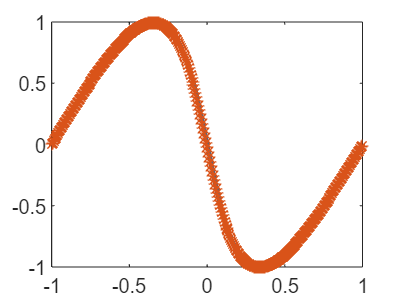

err1 = abs(y-yy);
plot(xx,y,'LineWidth',2)
hold on
plot(xx,yy,'*')

num

num = 320

disp(norm(err1,inf))

   6.6427e-04

